## Controls Systems Textbook Example 10.8

### Reset matlab environment

clearvars
close all
clc
s = tf('s');

### Specs: $P.M.=70\degree,\ K_v\ge20$


$$L(s)=G_C(s)G(s)=\frac{K}{s(s+10)^2}$$


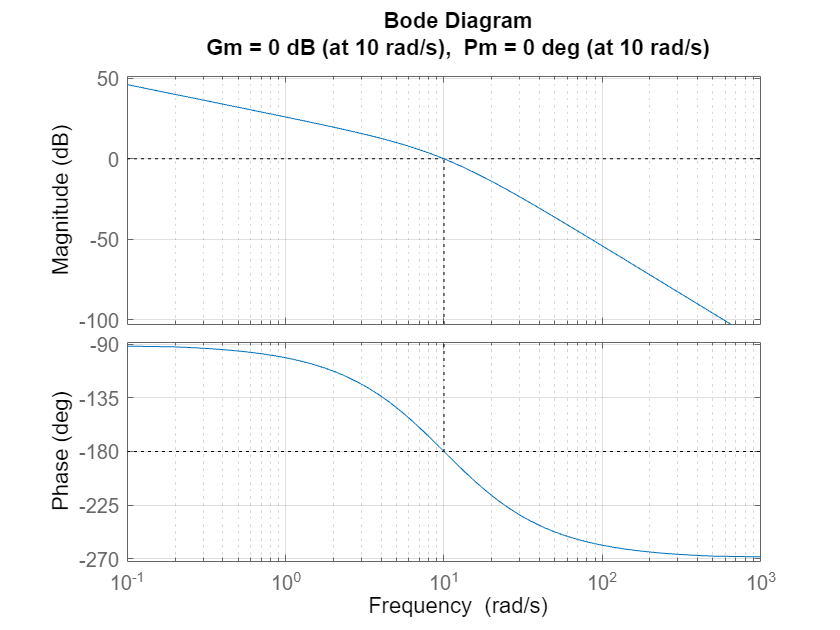

G = 1 / (s * (s + 10)^2);   % type 1
K = 2000;
margin(K * G), grid

### Design of a phase-lag compensator


$$20\log_{10}\alpha=25\text{ dB }\Rightarrow\alpha\approx17.78\\
\text{Notice that the general rule of thumb (see ex10\_8.mlx) is not working here.}\\
\text{Therefore, we find the new crossover frequency }\omega'_c=1.11\text{rad/s}.\\
\Rightarrow z = \frac{\omega'_c}{\alpha},\ p = \frac{z}{\alpha}$$


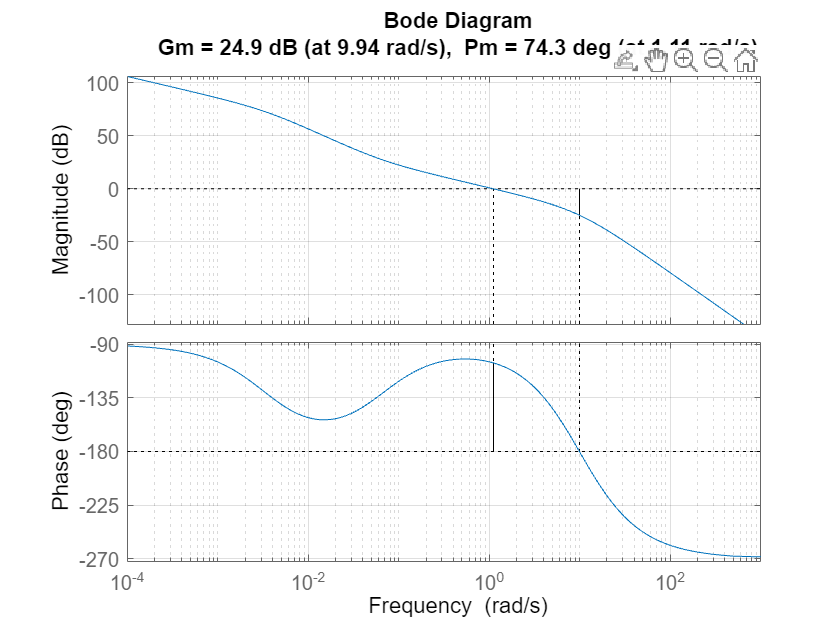

pzratio = 17.78;
omega_c = 1.11;
z = omega_c / pzratio;
p = z / pzratio;
G_C = K * (p / z) * (s + z) / (s + p);
L = G_C * G;
margin(L), grid

K_V = evalfr(s * L, 10^-10)

K_V = 20.0000